% SPF non ci interessa perchè è una previsione da parte di professionisti
% dobbiamo lavorare solo con la colonna di rifeimento
% preliminary stuff 
clear all; close all; clc

data = readmatrix("2019-04.csv")

data = 1.0e+07 *

       NaN         0         0    0.0000    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

S_PDivYield = data(4:189,248)

S_PDivYield =     3.1012
    3.0720
    3.1572
    3.3850
    3.4726
    3.5002
    3.5259
    3.1370
    2.9402
    2.9234


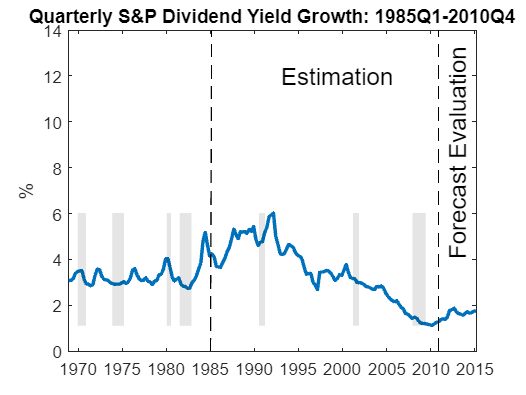


save esametimetrimestrale.mat

load('esametimetrimestrale.mat')

t = datetime(1968,12,01):calquarters(1):datetime(2015,03,01); t =t';

plot(t,S_PDivYield,'linewidth',2); axis tight; recessionplot;
title('Quarterly S&P Dividend Yield Growth: 1985Q1-2010Q4'); ylabel('%'); hold on;
plot([datetime(1985,01,01) datetime(1985,03,01)],[0 14],'--k'); hold on
plot([datetime(2010,12,01) datetime(2010,12,01)],[0 14],'--k'); hold off
text([datetime(1993,1,01)],12,'Estimation','Fontsize',14);
text([datetime(2013,1,01)],4,'Forecast Evaluation','Fontsize',14,'Rotation',90);

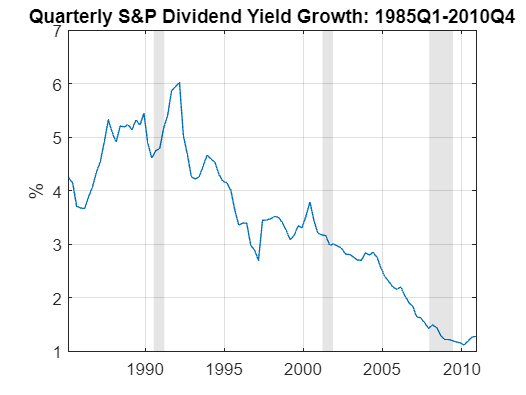


t_est = (datetime(1985,3,01):calquarters(1):datetime(2010,12,01))';
y = S_PDivYield(ismember(t,t_est));
plot(t_est,y); recessionplot;
title('Quarterly S&P Dividend Yield Growth: 1985Q1-2010Q4'); ylabel('%'); grid on

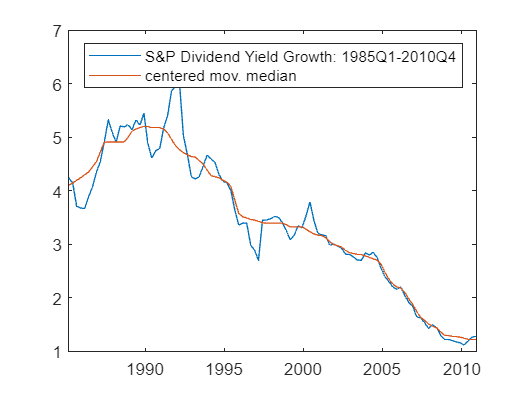

plot(t_est,[y movmedian(y,4*5)]);
legend('S&P Dividend Yield Growth: 1985Q1-2010Q4','centered mov. median')

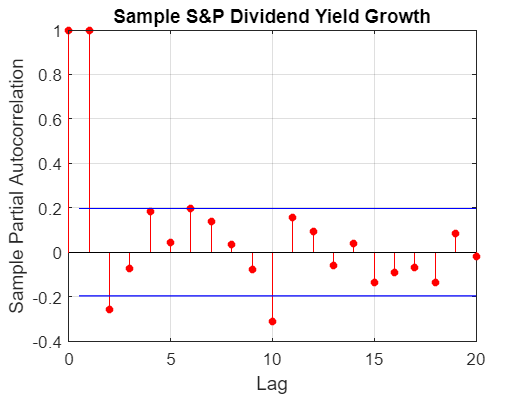


parcorr(y,4*5); title('Sample S&P Dividend Yield Growth')

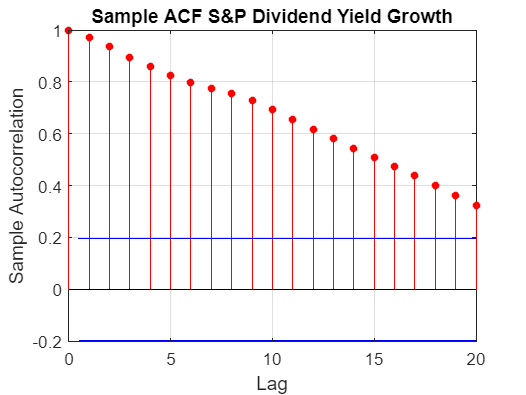


autocorr(y,4*5); title('Sample ACF S&P Dividend Yield Growth')

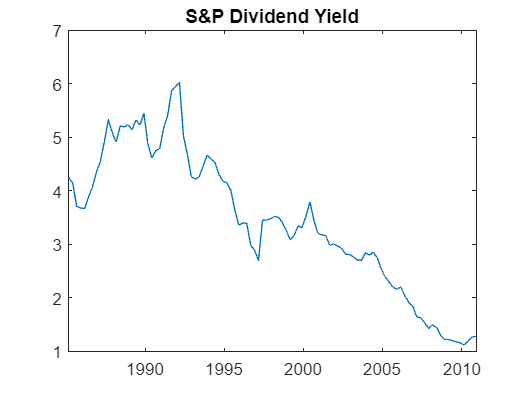


%nei primi 4 punti dell'esame non devo utilizzare la differenza prima


%t_est2 = (datetime(1985,6,01):calquarters(1):datetime(2010,12,01))';
%y2 = diff(y)

%plot(t_est2,y2); title('First difference of S&P Dividend Yield Growth: 1985Q1-2010Q4')

%autocorr(y2,20); title('ACF \Delta First difference of S&P Dividend Yield');
%parcorr(y2,20); title('PACF \Delta First difference of S&P Dividend Yield');

%Unit root test ho una radice unitaria perchè non posso rigettare H0

plot(t_est,y); title('S&P Dividend Yield');

maxlag = 4; % Max lags
[h,pValue,stat,cValue,reg] = adftest(y,'lags',0:maxlag,'model','ARD');
% find p that min BIC
reg.BIC

ans = -11.4613

ans = -12.6499

ans = -10.6384

ans = -8.4735

ans = -2.7983

[h,pValue,stat,cValue] = adftest(y,'lags',2,'model','ARD')

h = logical
   0


pValue = 0.8676

stat = -0.5847

cValue = -2.8895

%Model selection (Model in Level): ARMA for inflation
pmax = 4; qmax = 4; %(Y,CONSTANT,P,Q,X,STARTINGVALS,OPTIONS,HOLDBACK,SIGMA2)
aic=NaN(pmax+1,qmax+1); bic = aic;
const = 1;
for p = 0:pmax
    for q=0:qmax
        mdl = arima(p,0,q);
        [~,~,logL] = estimate(mdl,y,'Display','off');
        kk = (p+q+1); nobs=size(y,1)-pmax;
        aic(p+1,q+1) =(-2*logL/nobs)+(2*kk/nobs);
        bic(p+1,q+1) = (-2*logL/nobs)+(2*kk*log(nobs)/nobs);
    end
end

[popt,qopt] = find(aic==min(min(aic))); popt1=popt-1; qopt1=qopt-1;
[popt,qopt] = find(bic==min(min(bic))); popt2=popt-1; qopt2=qopt-1;
array2table([(0:pmax)' bic],...
    'VariableNames',{'p/q','0','1','2','3','4'})

ans = 5×6 table
    p/q        0           1           2           3          4   
    ___    _________    ________    ________    _______    _______

     0        3.5915      2.4512      1.6345     1.3373     1.0739
     1     -0.034588    0.002233    0.058908    0.14547    0.23695
     2     -0.013505    0.076259     0.14546    0.23724    0.32183
     3       0.07265      0.1436     0.23234    0.30866    0.34101
     4       0.12609     0.19708     0.32016     0.2907    0.34717


sprintf('Optimal lags, AIC: p = %1.0f \t q = %1.0f', popt1,qopt1)

ans = 'Optimal lags, AIC: p = 4 	 q = 4'

sprintf('Optimal lags, BIC: p = %1.0f \t q = %1.0f', popt2,qopt2)

ans = 'Optimal lags, BIC: p = 1 	 q = 0'

Proviamo con il modello ARMA (1,1)

% Estimate ARMA(1,1) and save residuals
mdl1 = arima(1,0,1);
arma11 = estimate(mdl1,y);

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    -0.0011586        0.12998      -0.0089136        0.99289
    AR{1}          0.99248       0.029973          33.112    1.9808e-240
    MA{1}           0.2027        0.13356          1.5177         0.1291
    Variance      0.044986      0.0047626          9.4456     3.5332e-21



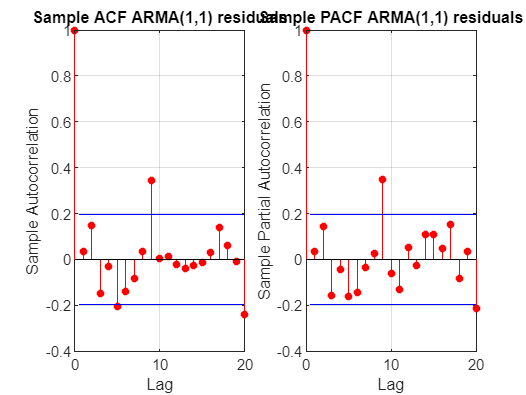

uhat = infer(arma11,y); % Residuals

subplot(1,2,1); autocorr(uhat,4*5); title('Sample ACF ARMA(1,1) residuals');
subplot(1,2,2); parcorr(uhat,4*5); title('Sample PACF ARMA(1,1) residuals');

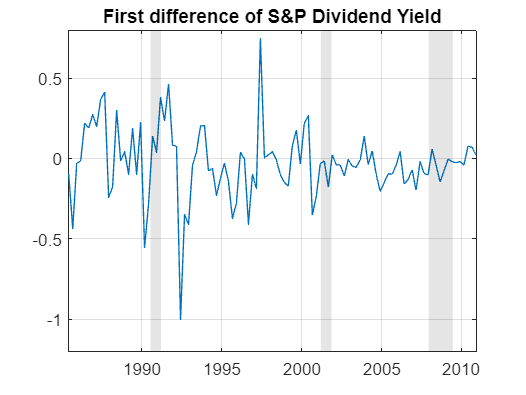


%Model in first differences ARIMA(p,1,q) for inflation, assumed to be unit root
dy = diff(y);
clf; plot(t_est(2:end),dy); recessionplot; axis tight; grid on; title('First difference of S&P Dividend Yield')


subplot(2,1,1); autocorr(dy,'NumLags',20); title('Sample ACF \Delta S&P Dividend Yield')
subplot(2,1,2); parcorr(dy,'NumLags',20);  title('Sample PACF \Delta S&P Dividend Yield')


Estimation and Validation (model in first differences):

mdl2 = arima(0,1,1);
[ima11,~,logL] = estimate(mdl2,y);

 
    ARIMA(0,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue  
                _________    _____________    __________    _________

    Constant    -0.027251       0.025711       -1.0599        0.28919
    MA{1}         0.19926        0.12458        1.5994        0.10973
    Variance     0.045051      0.0036619        12.303      8.762e-35



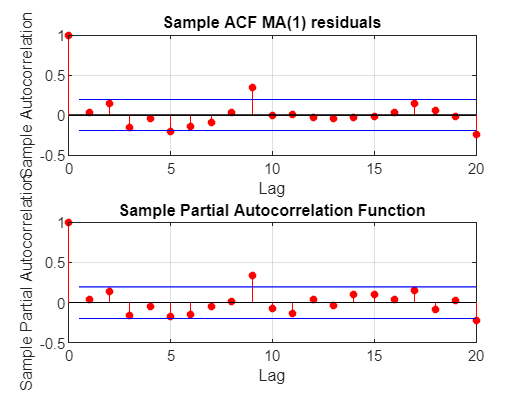


uhat = infer(ima11,y); % Residuals
subplot(2,1,1); autocorr(uhat,'NumLags',20); title('Sample ACF MA(1) residuals')
subplot(2,1,2); parcorr(uhat,'NumLags',20);  title('Sample MA(1) residuals')
subplot(2,1,2); parcorr(uhat,20); 

## Forecasting 

We consider four different forecasts, always on the interval 2011Q1-2014Q4. 

- F0: the forecast from the Survey of Professional Forecasters: the series spf

- F1: the forecast from the ARMA(1,1) assuming stationarity

- F2: the forecast from the MA(1) assuming a unit root

- F3: a naïve random walk forecast, in which inflation is forecasted as the last available observation

- F4: random walk with drift: $\text{infl}_t = c + \text{infl}_{t-1} + u_t $. In practice, we estimate a model for $\Delta \text{infl}_t = c  + u_t $, our forecast for $\Delta \text{infl}_{t+1|1} \text{ is } \hat{c}  $. Then $\text{infl}_{t+1|1} - \text{infl}_{t} = \hat{c} \ and \ \text{infl}_{t+1|1} = \hat{c} + \text{infl}_{t} $

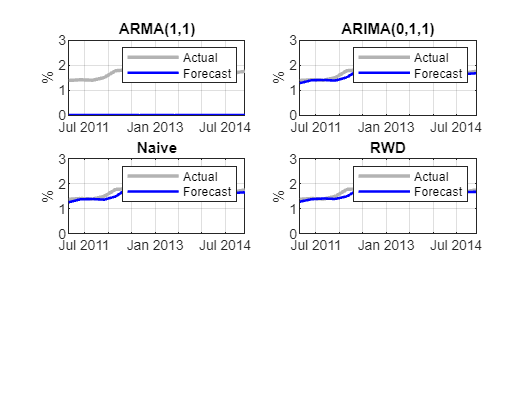

t_est_fore = (datetime(1985,3,01):calquarters(1):datetime(2014,12,01))';
t_fore = (datetime(2011,3,01):calquarters(1):datetime(2014,12,01))';

infl = S_PDivYield(ismember(t,t_est_fore));
actual = S_PDivYield(ismember(t,t_fore)); % Actual infl

t1 = find(t_est_fore=='01-Dec-2010'); % Last observation used to estimate the model
t2 = find(t_est_fore=='01-Sep-2014'); % Obs. to produce last 1-step ahead forecast
param1 = estimate(mdl1,infl(1:t1),'Display','off');
param2 = estimate(mdl2,infl(1:t1),'Display','off');
mdl3 = arima(0,1,0);
param3 = estimate(mdl3,infl(1:t1),'Display','off');

% Forecast f1 and f2
kk=1;

for jj=t1:t2
    fore(kk,2) = forecast(param1,1,infl(1:jj)); % ARIMA(1,0,1)
    fore(kk,3) = forecast(param2,1,infl(1:jj)); % ARIMA(0,1,1)
    fore(kk,4) = infl(jj); % Naive RW 
    fore(kk,5) = forecast(param3,1,infl(1:jj)); % ARIMA(0,1,0); RWD

    kk=kk+1;
end 

tit = {'ARMA(1,1)','ARIMA(0,1,1)','Naive','RWD'};
for ii = 1:4
    subplot(3,2,ii)
    plot(t_fore,actual,'linewidth',2,'Color',[.7 .7 .7]); hold on;
    plot(t_fore,fore(:,ii),'-b','linewidth',1.5); hold off; grid on; axis tight
    title(tit{ii}); ylim([0 3]); ylabel('%'); legend('Actual','Forecast')
end

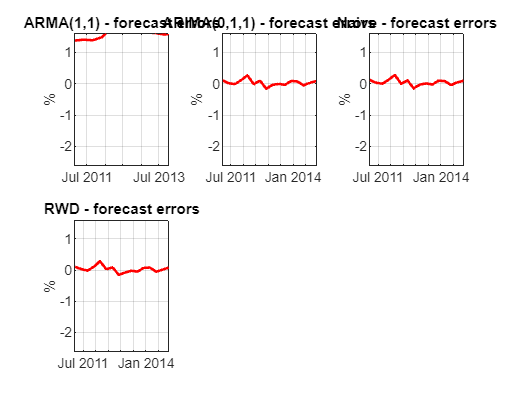



% Errors
u = actual-fore;
clf
for ii = 1:4
    subplot(2,3,ii)
    plot(t_fore,u(:,ii),'-r','linewidth',1.5); grid on; axis tight
    title([tit{ii} ' - forecast errors']); ylim([-2.6 1.6]); ylabel('%');
end

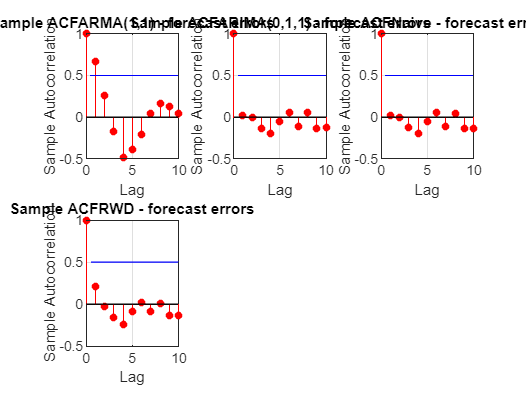


clf
for ii = 1:4
    subplot(2,3,ii)
    autocorr(u(:,ii),10); title(['Sample ACF' tit{ii} ' - forecast errors']);
end


mean(u.^2)

ans =     2.6925    0.0100    0.0111    0.0101    0.0125



%con i log
%y0 = 1985; y1 = 2010;
%time = y0+(1-1)/4:(1/4):y1+(3-1)/4;
%ylog = log(y(1:end-1))
%plot(time, ylog,'linewidth',3); axis tight; grid on
%legend('log S&P'); set(gca,'fontsize',18);
%autocorr(ylog,20); title('ACF \Delta  logS&P Dividend Yield');
%parcorr(ylog,20); title('PACF \Delta  logS&P Dividend Yield')

%ylog2 = diff(ylog)

%plot(ylog2); title('First difference of logS&P Dividend Yield Growth: 1985Q1-2010Q4')

%autocorr(ylog2,20); title('ACF \Delta First difference of logS&P Dividend Yield');
%parcorr(ylog2,20); title('PACF \Delta First difference of logS&P Dividend Yield')


